## Parameters

fun = @fs;
nvar = 2;

## **Optimization Task**

Use** LIVE EDITOR->CODE->TASK->Optimize **to init a optimization live script task.

Optimization terminated: maximum number of generations exceeded.


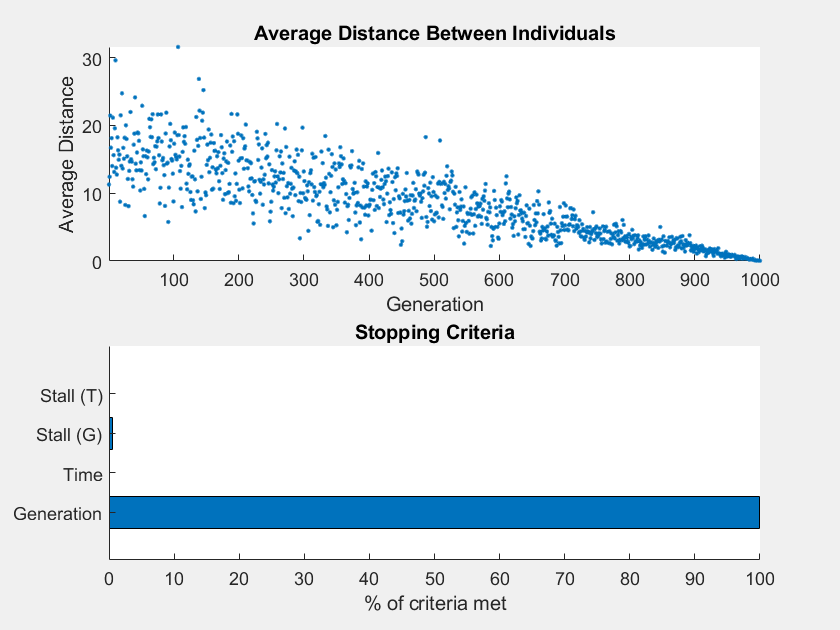

% Set nondefault solver options
options = optimoptions("ga","MaxStallGenerations",500,"MaxGenerations",1000,...
    "FunctionTolerance",1e-08,"PlotFcn",["gaplotdistance","gaplotstopping"]);

% Solve
[solution,objectiveValue] = ga(fun,nvar,[],[],[],[],[],[],[],[],options);


% Clear variables
clearvars options

## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. You can see and modify these variable names at the top of the `Optimize` task.

View these variables.

solution

solution =     1.0077    1.0176


objectiveValue

objectiveValue = 5.2270e-04